1.绘制图像


$$f(x, y) = sin^2(3\pi x)+(x-1)^2(1+sin^2(3\pi y))+(y-1)^2(1+sin^2(2\pi y))$$


clc;
clf;
all clear;

x = -5:0.1:5;
y = -5:0.1:5;
[X,Y] = meshgrid(x, y);
[n, m] = size(X);
vX = reshape(X, m*n, 1);
vY = reshape(Y, m*n, 1);
newX = [vX, vY];
vZ = levin13fcn(newX);    % 调用levin13fcn函数
Z = reshape(vZ, n, m);



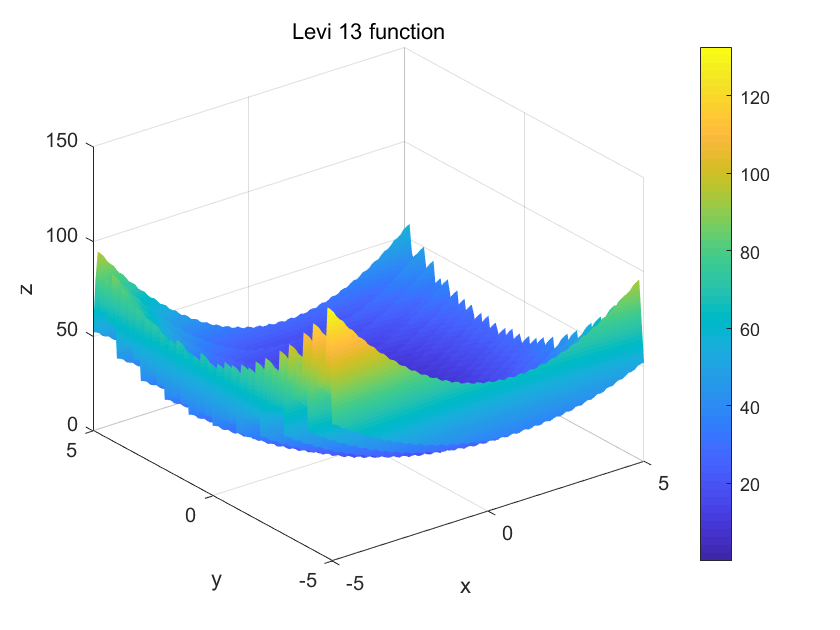

figure(1);
surf(X, Y, Z);
xlabel('x');
ylabel('y');
zlabel('z')
title('Levi 13 function');
shading interp;
colorbar;

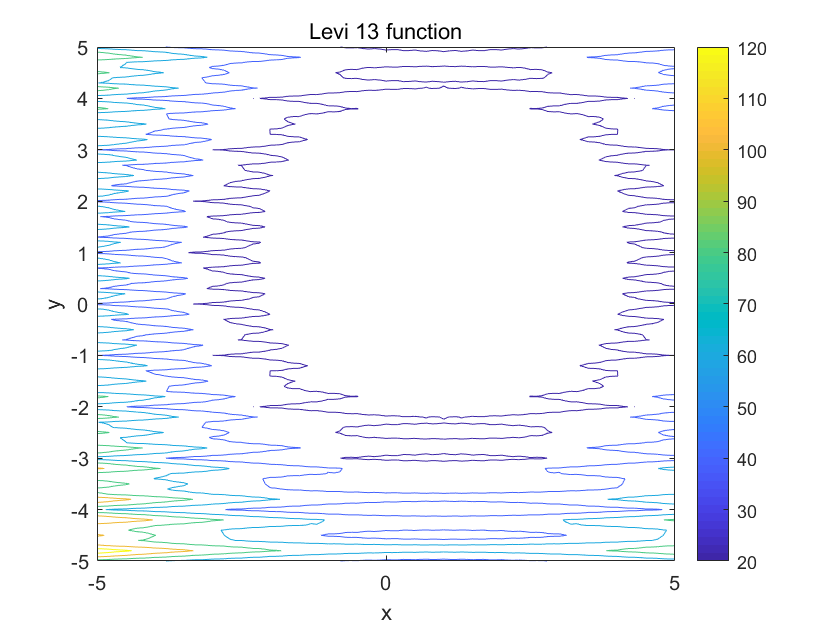

figure(2)
contour(X, Y, Z);
xlabel('x');
ylabel('y');
zlabel('z')
title('Levi 13 function');

colorbar;

syms x y;
f = sin(3 * pi * x) ^ 2 + ...
        ((x - 1) ^2) * (1 + sin(3 * pi * y) ^ 2) + ...
        ((y - 1) ^2) * (1 + sin(2 * pi * y) ^ 2);
gx = diff(f, x)

$$ans = \left(2\,x-2\right)\,\left({\sin\left(3\,\pi \,y\right)}^{2}+1\right)+6\,\pi \,\cos\left(3\,\pi \,x\right)\,\sin\left(3\,\pi \,x\right)$$

gy = diff(f, y)

$$ans = \left(2\,y-2\right)\,\left({\sin\left(2\,\pi \,y\right)}^{2}+1\right)+6\,\pi \,\cos\left(3\,\pi \,y\right)\,\sin\left(3\,\pi \,y\right)\,{\left(x-1\right)}^{2}+4\,\pi \,\cos\left(2\,\pi \,y\right)\,\sin\left(2\,\pi \,y\right)\,{\left(y-1\right)}^{2}$$

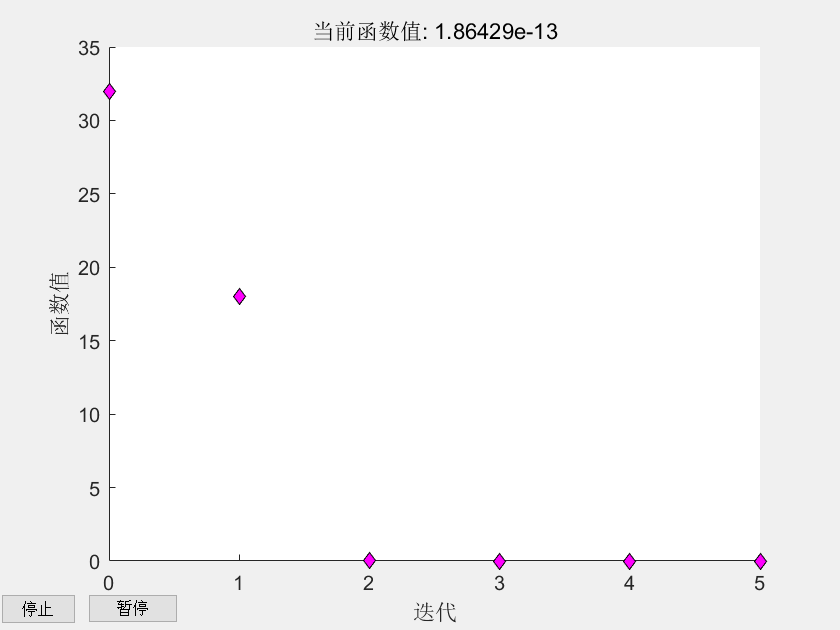

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3               32                             8
     1           6          18.0001       0.124998              6  
     2           9        0.0038055              1           1.17  
     3          18      7.82744e-06       0.012215         0.0529  
     4          21      1.47684e-10              1       0.000139  
     5          24      1.86429e-13              1       8.45e-07  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the 

x =     1.0000
    1.0000


options = optimoptions(@fminunc,'Display','iter','Algorithm','quasi-newton','PlotFcn','optimplotfval');
x0 = [5; 5];
fun = @levin13_with_grad;
x = fminunc(fun,x0,options)

x_ = fminsearch(fun, x0)

x_ =     1.0000
    4.9936


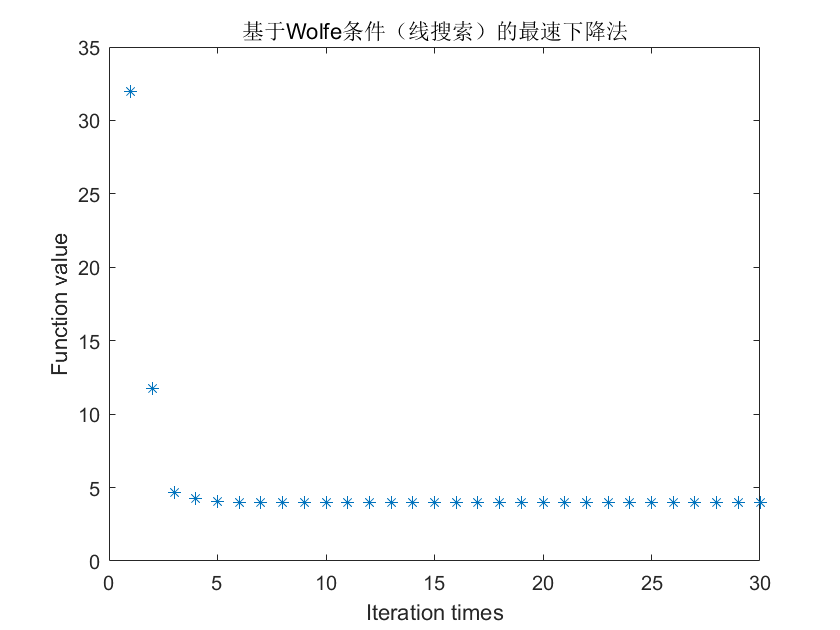

[x, fx, count] = SteepestDescent(@levin13_with_grad, @BackTracking, x0, 1e5);
plot(1:1:count, fx, '*');
xlabel('Iteration times');
ylabel('Function value');
title('基于Wolfe条件（线搜索）的最速下降法');